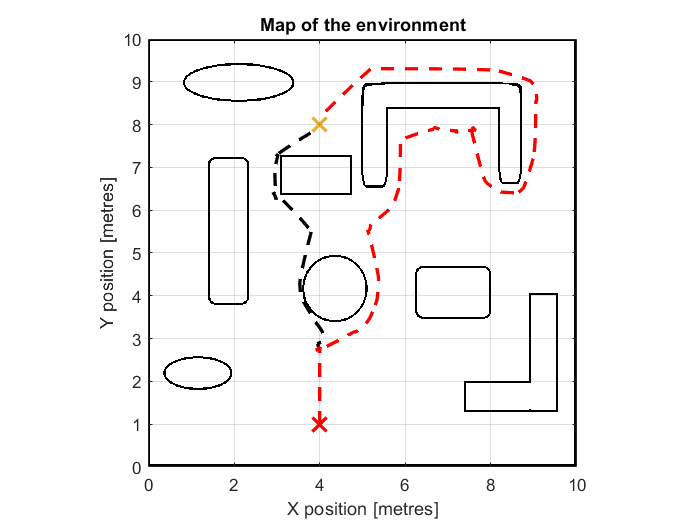

load("T2_experiment1.mat");
figure(1);
%clf; 
show(obstacleMap);grid on; hold on;
xlabel('X position [metres]');
ylabel('Y position [metres]');
title('Map of the environment');
 % plot the goal point
goalPlot(1) = plot(start(2),start(1),'Marker','x','MarkerEdgeColor','red',...
    'LineWidth',2,'MarkerSize',12);
goalPlot(2) = plot(goal(2),goal(1),'Marker','x','MarkerEdgeColor','[0.9290, 0.6940, 0.1250]',...
    'LineWidth',2,'MarkerSize',12);
set(goalPlot,'linestyle','none');
trajectory(1) = plot(xio(:,20)+5,xio(:,19)+5,'k','LineStyle','--','LineWidth',2);
trajectory(1).Color(4) = 0.5;
load("T2_experiment1_Right_Tenacity.mat");
trajectory(2) = plot(xio(:,20)+5,xio(:,19)+5,'red','LineStyle','--','LineWidth',2);
trajectory(2).Color(4) = 0.5;

legend([goalPlot(1:2) trajectory(1:2)],{'Start','Goal','Left Tenacity Path','Right Tenacity Path'},'FontSize',11); 

Error using legend (line 178)
Handle inputs of type Line cannot be used with this function.

q_arr=[4 7];
for i=1:length(q_arr)
    q = q_arr(i);
    drawrobot(0.2,plotStorage(q,1),plotStorage(q,2),plotStorage(q,3),'b');
    cntr = q_arr(i);
     for k=1:K
        angle = sectorPlotStorage(cntr).env.angle(k);
        sector = sectorPlotStorage(cntr).env.sector(k);
        cur_x = sectorPlotStorage(cntr).pos(1);
        cur_y = sectorPlotStorage(cntr).pos(2);
        R = sectorPlotStorage(cntr).R;
        drawSectors(angle,cur_x,cur_y,sector,K,k,R,range)
    end
end